# Data Exploration

First, download the data.

Look at the following links for lists of cities and the corresponding filenames:

- [US Cities](https://academic.udayton.edu/kissock/http/Weather/citylistUS.htm)

- [International Cities](https://academic.udayton.edu/kissock/http/Weather/citylistWorld.htm)

Pick your favourite city from the list and in the cell below change the filename to download `file`, and the name you want to give it when it's downloaded, `saveas`. Then call the function `get_raw_data`. 

clear;clc

% Download and extract the raw data if needed (skip if you already have it
% from a previous exercise)
file = "32874107";
local_filename = "milton_MA.csv";
% get_raw_data('file', file, 'local_filename', local_filename);

Then read the data into MATLAB:

data = read_temperature_file(fullfile("data", local_filename));
summary(data)

Variables:

    date: 46683×1 datetime

        Values:

            Min       1893-01-01
            Median    1957-05-08
            Max       2021-11-27

    tmax: 46683×1 double

        Values:

            Min       -19.444 
            Median     14.444 
            Max        38.333 

    tmin: 46683×1 double

        Values:

            Min       -29.444 
            Median          5 
            Max        26.111 



head(data)

       date         tmax       tmin  
    __________    ________    _______

    1893-01-01      3.3333    -5.5556
    1893-01-04     -8.8889    -16.111
    1893-01-05     -2.7778    -10.556
    1893-01-06     -8.3333    -13.333
    1893-01-07     -6.6667    -14.444
    1893-01-08     -6.6667    -11.667
    1893-01-09     -2.7778    -16.111
    1893-01-10    -0.55556    -15.556



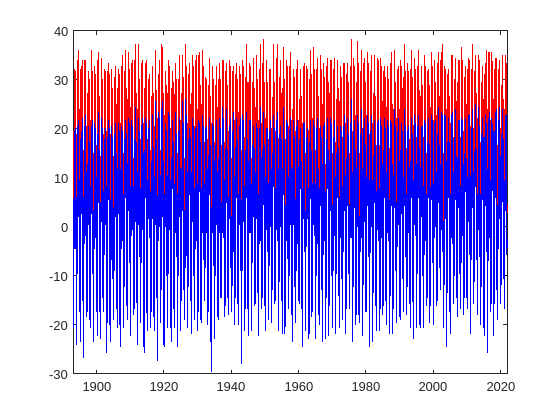

plot(data.date, data.tmax, 'r', ...
    data.date, data.tmin, 'b')

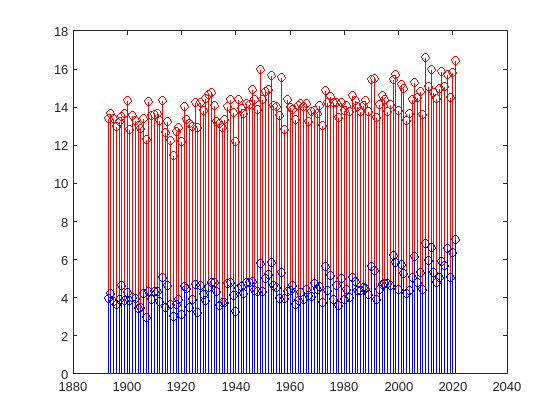

tt = table2timetable(data);
yearly_mean = retime(tt, "yearly", "mean");
scatter(yearly_mean.date.Year, yearly_mean.tmax, 'r'); hold on
scatter(yearly_mean.date.Year, yearly_mean.tmin, 'b');